## Load data

clear all
% Yb-171 \sigma_x
main_dir='\\Artemis-pc\e\Data\2022-08-05\Abs-10412';
load([main_dir,'\average.mat'],'phase_mean','phase_std','xlist');
t_171_0=xlist;
P_171_0=phase_mean;
P_171_0_std=phase_std;
P_171_0_weight=1./P_171_0_std.^2;

clear main_dir phase_mean phase_std xlist

% Yb-173 0\sigma_x+1\sigma_x^2
main_dir='\\Artemis-pc\e\Data\2022-10-18\Abs-8658';
load([main_dir,'\average.mat'],'phase_mean','phase_std','xlist');
t_173_0=xlist;
P_173_0=phase_mean;
P_173_0_std=phase_std;
P_173_0_weight=1./P_173_0_std.^2;
clear main_dir phase_mean phase_std xlist

% Yb-173 1\sigma_x+1\sigma_x^2
main_dir='\\Artemis-pc\e\Data\2022-09-30\Abs-5782';
load([main_dir,'\average.mat'],'phase_mean','phase_std','xlist');
t_173_1=xlist;
P_173_1=phase_mean;
P_173_1_std=phase_std;
P_173_1_weight=1./P_173_1_std.^2;
clear main_dir phase_mean phase_std xlist

% Yb-173 1\sigma_x+2\sigma_x^2
main_dir='\\Artemis-pc\e\Data\2022-10-17\Abs-7616';
load([main_dir,'\average.mat'],'phase_mean','phase_std','xlist');
t_173_2=xlist;
P_173_2=phase_mean;
P_173_2_std=phase_std;
P_173_2_weight=1./P_173_2_std.^2;
clear main_dir phase_mean phase_std xlist

## Data fit

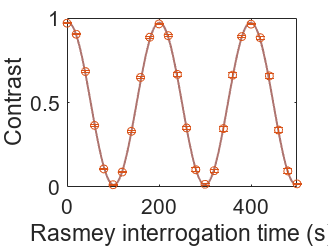

colors=npg(100); 
% Model
% cos(phi)/2 + 1/2
%(5*cos(2*phi))/32 + (5*cos(2*phi)^2)/64 + (5*cos(2*phi)^3)/16 + 29/64
%((cos(phi) + 1)^3*(9*cos(phi)^2 - 12*cos(phi) - 10*cos(phi)^3 + 60*cos(phi)^4 - 90*cos(phi)^5 + 40*cos(phi)^6 + 4))/8
%(5*cos(3*phi) + 5*cos(6*phi) + cos(10*phi) + cos(15*phi) + 10*cos(phi) + 10)^2/1024 + (5*sin(3*phi) + 5*sin(6*phi) + sin(10*phi) + sin(15*phi) + 10*sin(phi))^2/1024
 
% Yb-171 1\sigma_x+0\sigma_x^2
eqn='a*(cos(phi*2*pi*(x-e)/1000)/2 + 1/2)+b';
startpoints=[1 0 0 5.0406];
lower=[0.8 -0.5 -10 4.5];
upper=[1.1  0.5 10 5.5];

fi=fit(t_171_0',P_171_0',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',P_171_0_weight,'Exclude',t_171_0 > 500);
f1=figure;
h2=plot((1:1:2000),fi(1:1:2000),'LineWidth',1.5,'Color',colors(5,:));
hold on
h3=errorbar(t_171_0',P_171_0,P_171_0_std,'o');

xlim([0 500])
ylim([0 1])
set(gca,'FontSize',16)
xlabel('Rasmey interrogation time (s)')
ylabel('Contrast')

fi.phi

ans = 5.0406

fi.e

ans = 2.3716

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans =     0.0045    0.0031    0.3922    0.0108


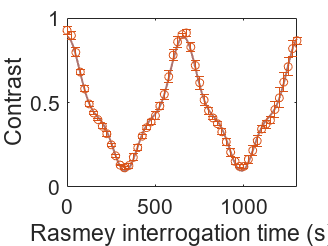





% Yb-173 0\sigma_x+1\sigma_x^2
eqn='a*((5*cos(2*phi*x*(2*pi)/1000))/32+(5*cos(2*phi*x*(2*pi)/1000)^2)/64+(5*cos(2*phi*x*(2*pi)/1000)^3)/16+29/64)+b';
startpoints=[1 0 0.7606];
lower=[0.8 -0.5 0.6];
upper=[1.1  0.5 0.85];

fi=fit(t_173_0',P_173_0',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',P_173_0_weight,'Exclude',t_173_0 > 1300);
f1=figure;
h2=plot((1:1:2000),fi(1:1:2000),'LineWidth',1.5,'Color',colors(5,:));
hold on
h3=errorbar(t_173_0',P_173_0,P_173_0_std,'o');

xlim([0 1300])
ylim([0 1])
set(gca,'FontSize',16)
xlabel('Rasmey interrogation time (s)')
ylabel('Contrast')

fi.phi

ans = 0.7606

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans =     0.0078    0.0035    0.0015


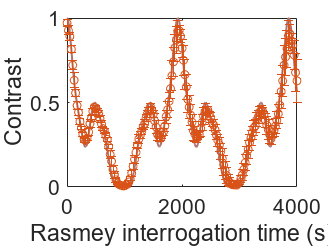


% Yb-173 1\sigma_x+1\sigma_x^2
eqn='(((cos(phi*x/1000*2*pi) + 1)^3*(9*cos(phi*x/1000*2*pi)^2 - 12*cos(phi*x/1000*2*pi) - 10*cos(phi*x/1000*2*pi)^3 + 60*cos(phi*x/1000*2*pi)^4 - 90*cos(phi*x/1000*2*pi)^5 + 40*cos(phi*x/1000*2*pi)^6 + 4))/8)';
startpoints=[0.5181];
lower=[0.4];
upper=[0.6];

fi=fit(t_173_1',P_173_1',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',P_173_1_weight,'Exclude',t_173_1 > 4000);
f1=figure;
h2=plot((1:1:4000),fi(1:1:4000),'LineWidth',1.5,'Color',colors(5,:));
hold on
h3=errorbar(t_173_1',P_173_1,P_173_1_std,'o');

xlim([0 4000])
ylim([0 1])
set(gca,'FontSize',16)
xlabel('Rasmey interrogation time (s)')
ylabel('Contrast')

fi.phi

ans = 0.5187

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans = 5.7056e-04

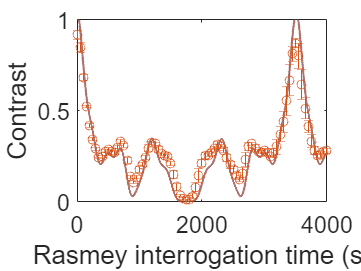



% Yb-173 1\sigma_x+2\sigma_x^2
eqn='a*((5*cos(3*phi*x*2*pi/1000) + 5*cos(6*phi*x*2*pi/1000) + cos(10*phi*x*2*pi/1000) + cos(15*phi*x*2*pi/1000) + 10*cos(phi*x*2*pi/1000) + 10)^2/1024 + (5*sin(3*phi*x*2*pi/1000) + 5*sin(6*phi*x*2*pi/1000) + sin(10*phi*x*2*pi/1000) + sin(15*phi*x*2*pi/1000) + 10*sin(phi*x*2*pi/1000))^2/1024)';
startpoints=[1  0.2855];
lower=[0.8  0.25];
upper=[1.1  0.3];

fi=fit(t_173_2',P_173_2',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',P_173_2_weight,'Exclude',t_173_2 > 4000);
f1=figure;
h2=plot((1:1:4000),fi(1:1:4000),'LineWidth',1.5,'Color',colors(5,:));
hold on
h3=errorbar(t_173_2',P_173_2,P_173_2_std,'o');

xlim([0 4000])
ylim([0 1])
set(gca,'FontSize',16)
xlabel('Rasmey interrogation time (s)')
ylabel('Contrast')

fi.phi

ans = 0.2849

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans =     0.0202    0.0011


## Hamitonian

% Yb-171 \sigma_x
clear init finalstate finalpop

init=[ 1 0 ];
init=init';
sigmax=spinOp(1/2,'x');
sigmay=spinOp(1/2,'y');
sigmaz=spinOp(1/2,'z');

omega_171_0_v=2*pi*5.0406/1000; % 5.0406kHz
% 常规模型:
%      f(x) = a*sin(2*pi*b*x+c)+d
% 系数(置信边界为 95%):
%        a =      0.4784  (0.4749, 0.4818)
%        b =     0.00504  (0.005028, 0.005052)
%        c =       7.778  (7.759, 7.796)
%        d =      0.4919  (0.4889, 0.495)

ham_1=omega_171_0_v*sigmax;

timelist_171_0=(0:1:800);
finalstate=zeros(length(init),length(timelist_171_0));
k=1;
for t=timelist_171_0
    evo=ham_1.*t.*1i;
    finalstate(:,k)=expm(-evo)*init;
    k=k+1;
end
finalpop(:,:)=abs(finalstate(:,:)).^2;
finalpop_171_0=finalpop(:,:);
figure
plot(timelist_171_0,finalpop(1,:));
hold on
errorbar(t_171_0-2.3716,P_171_0,P_171_0_std,'o');
ylim([0 1])
t_171_0_N=(t_171_0-2.3716)*5.0406/1000;
timelist_171_0_N=timelist_171_0*5.0406/1000;

% Yb-173 0\sigma_x+1\sigma_x^2

clear init  finalstate finalpop

init=[ 1 0 0 0 0 0 ];
init=init';
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');

omega_173_0_t=2*pi*0.7606/1000;
ham_2=omega_173_0_t*sigmax^2;

timelist_173_0=(0:10:4000);
finalstate=zeros(length(init),length(timelist_173_0));
k=1;
for t=timelist_173_0
    evo=ham_2.*t.*1i;
    finalstate(:,k)=expm(-evo)*init;
    k=k+1;
end
finalpop(:,:)=abs(finalstate(:,:)).^2;
finalpop_173_0=finalpop(:,:);
figure
plot(timelist_173_0,finalpop(1,:));
hold on
errorbar(t_173_0,P_173_0,P_173_0_std,'o');
ylim([0 1])

t_173_0_N=t_173_0*0.7606/1000;
timelist_173_0_N=timelist_173_0*0.7606/1000;

% Yb-173 1\sigma_x+1\sigma_x^2

clear init finalstate finalpop

init=[ 1 0 0 0 0 0 ];
init=init';
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');

omega_173_1_v=2*pi*0.5187/1000;
omega_173_1_t=omega_173_1_v;
ham_3=omega_173_1_v*sigmax+omega_173_1_t*sigmax^2;

timelist_173_1=(0:25:10000);
finalstate=zeros(length(init),length(timelist_173_1));
k=1;
for t=timelist_173_1
    evo=ham_3.*t.*1i;
    finalstate(:,k)=expm(-evo)*init;
    k=k+1;
end
finalpop(:,:)=abs(finalstate(:,:)).^2;
finalpop_173_1=finalpop(:,:);
figure
plot(timelist_173_1,finalpop(1,:));
hold on
errorbar(t_173_1,P_173_1,P_173_1_std,'o');
ylim([0 1])

t_173_1_N=t_173_1*0.5181/1000;
timelist_173_1_N=timelist_173_1*0.5181/1000;

% Yb-173 1\sigma_x+2\sigma_x^2

clear init finalstate finalpop

init=[ 1 0 0 0 0 0 ];
init=init';
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');

omega_173_2_v=2*pi*0.2855/1000;
omega_173_2_t=2*omega_173_2_v;
ham_4=omega_173_2_v*sigmax+omega_173_2_t*sigmax^2;

timelist_173_2=(0:25:10000);
finalstate=zeros(length(init),length(timelist_173_2));
k=1;
for t=timelist_173_2
    evo=ham_4.*t.*1i;
    finalstate(:,k)=expm(-evo)*init;
    k=k+1;
end
finalpop(:,:)=abs(finalstate(:,:)).^2;
finalpop_173_2=finalpop(:,:);
figure
plot(timelist_173_2,finalpop(1,:));
hold on
errorbar(t_173_2,P_173_2,P_173_2_std,'o');
ylim([0 1])

t_173_2_N=t_173_2*0.2855/1000;
timelist_173_2_N=timelist_173_2*0.2855/1000;


## Data normalization

% 1
figure
box on

h_171_0=errorbar(t_171_0_N*2*pi,P_171_0,P_171_0_std,'o');

%2
figure
box on

h_173_0=errorbar(t_173_0,P_173_0,P_173_0_std,'o');
%3
figure
box on

h_173_1=errorbar(t_173_1,P_173_1,P_173_1_std,'o');
%4
figure
box on

h_173_2=errorbar(t_173_2,P_173_2,P_173_2_std,'o');

## Subplot

colors=npg(100); 

x_label='Pulse length us';
x_lim_low=0;
x_lim_high=10000;
y_lim_low=0;
y_lim_high=1.0;


% xlabel(x_label)
% ylabel('Sz')
% set(gca,'FontSize',16)
% xlim([x_lim_low x_lim_high])
% ylim([y_lim_low y_lim_high])
figure
clear ha pos
[ha, pos] = tight_subplot(2, 2, [0.15 0.10], [0.1 0.1], [0.1 0.03]);

%sub plot 1
axes(ha(1))
box on

h_171_0_line=plot(timelist_171_0_N*2*pi,finalpop_171_0(1,:));
hold on
h_171_0_point=errorbar(t_171_0_N*2*pi,P_171_0,P_171_0_std,'o');




%sub plot 2
axes(ha(2))
box on

h_173_0_line=plot(timelist_173_0_N*2*pi,finalpop_173_0(1,:));
hold on
h_173_0_point=errorbar(t_173_0_N*2*pi,P_173_0,P_173_0_std,'o');


%sub plot 3
axes(ha(3))
box on

h_173_1_line=plot(timelist_173_1_N*2*pi,finalpop_173_1(1,:));
hold on
h_173_1_point=errorbar(t_173_1_N*2*pi,P_173_1,P_173_1_std,'o');


%sub plot 4
axes(ha(4))
box on

h_173_2_line=plot(timelist_173_2_N*2*pi,finalpop_173_2(1,:));
hold on
h_173_2_point=errorbar(t_173_2_N*2*pi,P_173_2,P_173_2_std,'o');


## Plot Style

% % Subplot1
% axes(ha(1))
% 
% h_171_0_line.Color=colors(44,:);
% 
% h_171_0_point.MarkerSize=4;
% h_171_0_point.Color=colors(80,:);
% h_171_0_point.MarkerEdgeColor=colors(80,:);
% h_171_0_point.MarkerFaceColor=colors(44,:);
% h_171_0_point.CapSize=0;
% 
% %set(gca,'TickLabelInterpreter','latex')
% set(gca,'XTickLabelRotation',0)
% set(gca,'FontSize',10)
% xticks(0:pi/2:4*pi)
% xticklabels({'0','\pi/2','\pi','3/2\pi','2\pi','5/2\pi','3\pi','7/2\pi','4\pi'})
% xlim([0 4*pi])
% ylim([0 1])
% xlabel('$\phi$','Interpreter','latex')
% ylabel('$P_{+\frac{1}{2}}$','Interpreter','latex')
% 
% % Subplot2
% axes(ha(2))
% 
% h_173_0_line.Color=colors(55,:);
% 
% h_173_0_point.MarkerSize=4;
% h_173_0_point.Color=colors(34,:);
% h_173_0_point.MarkerEdgeColor=colors(34,:);
% h_173_0_point.MarkerFaceColor=colors(55,:);
% h_173_0_point.CapSize=0;
% %set(gca,'TickLabelInterpreter','latex')
% set(gca,'XTickLabelRotation',0)
% set(gca,'FontSize',10)
% xticks(0:pi/2:4*pi)
% xticklabels({'0','\pi/2','\pi','3/2\pi','2\pi','5/2\pi','3\pi','7/2\pi','4\pi'})
% xlim([0 4*pi])
% ylim([0 1])
% xlabel('$\phi$','Interpreter','latex')
% ylabel('$P_{+\frac{5}{2}}$','Interpreter','latex')
% 
% % Subplot3
% axes(ha(3))
% h_173_1_line.Color=colors(12,:);
% 
% h_173_1_point.MarkerSize=4;
% h_173_1_point.Color=colors(31,:);
% h_173_1_point.MarkerEdgeColor=colors(31,:);
% h_173_1_point.MarkerFaceColor=colors(12,:);
% h_173_1_point.CapSize=0;
% %set(gca,'TickLabelInterpreter','latex')
% set(gca,'XTickLabelRotation',0)
% set(gca,'FontSize',10)
% xticks(0:pi/2:4*pi)
% xticklabels({'0','\pi/2','\pi','3/2\pi','2\pi','5/2\pi','3\pi','7/2\pi','4\pi'})
% xlim([0 4*pi])
% ylim([0 1])
% xlabel('$\phi$','Interpreter','latex')
% ylabel('$P_{+\frac{5}{2}}$','Interpreter','latex')
% % Subplot4
% axes(ha(4))
% h_173_2_line.Color=colors(65,:);
% 
% h_173_2_point.MarkerSize=4;
% h_173_2_point.Color=colors(26,:);
% h_173_2_point.MarkerEdgeColor=colors(26,:);
% h_173_2_point.MarkerFaceColor=colors(65,:);
% h_173_2_point.CapSize=0;
% 
% %set(gca,'TickLabelInterpreter','latex')
% set(gca,'XTickLabelRotation',0)
% set(gca,'FontSize',10)
% xticks(0:pi/2:4*pi)
% xticklabels({'0','\pi/2','\pi','3/2\pi','2\pi','5/2\pi','3\pi','7/2\pi','4\pi'})
% xlim([0 4*pi])
% ylim([0 1])
% xlabel('$\phi$','Interpreter','latex')
% ylabel('$P_{+\frac{5}{2}}$','Interpreter','latex')
% saveas(ha(1),['\\Artemis-pc\e\Data\DataForPub','\Figure1.png'])
% print(gcf, ['\\Artemis-pc\e\Data\DataForPub','\Figure2.png'],'-r300','-dpng');


## tiled layout

f=figure
f.Color='w';
f.Units='inches';
f.Position=[1 1 6 4];

t = tiledlayout(2,2,'TileSpacing','tight','Padding','tight');

%Plot 1
nexttile(1);
box on

h_171_0_line=plot(timelist_171_0_N*2*pi,finalpop_171_0(1,:));
hold on
h_171_0_point=errorbar(t_171_0_N*2*pi,P_171_0,P_171_0_std,'o');

set(gca,'XTickLabelRotation',0)
set(gca,'FontSize',10)
xticks(0:pi/2:4*pi)
xticklabels({'0','\pi/2','\pi','3/2\pi','2\pi','5/2\pi','3\pi','7/2\pi','4\pi'})
xlim([0 4*pi])
ylim([0 1])
xlabel('$\phi$','Interpreter','latex')
ylabel('$P_{+\frac{1}{2}}$','Interpreter','latex')

text(-pi/1.2,1,'a','FontWeight','bold')

%sub plot 2
nexttile(2);
box on

h_173_0_line=plot(timelist_173_0_N*2*pi,finalpop_173_0(1,:));
hold on
h_173_0_point=errorbar(t_173_0_N*2*pi,P_173_0,P_173_0_std,'o');

set(gca,'XTickLabelRotation',0)
set(gca,'FontSize',10)
xticks(0:pi/2:4*pi)
xticklabels({'0','\pi/2','\pi','3/2\pi','2\pi','5/2\pi','3\pi','7/2\pi','4\pi'})
xlim([0 4*pi])
ylim([0 1])
xlabel('$\phi$','Interpreter','latex')
ylabel('$P_{+\frac{5}{2}}$','Interpreter','latex')

text(-pi/1.2,1,'b','FontWeight','bold')

%sub plot 3
nexttile(3);
box on

h_173_1_line=plot(timelist_173_1_N*2*pi,finalpop_173_1(1,:));
hold on
h_173_1_point=errorbar(t_173_1_N*2*pi,P_173_1,P_173_1_std,'o');

set(gca,'XTickLabelRotation',0)
set(gca,'FontSize',10)
xticks(0:pi/2:4*pi)
xticklabels({'0','\pi/2','\pi','3/2\pi','2\pi','5/2\pi','3\pi','7/2\pi','4\pi'})
xlim([0 4*pi])
ylim([0 1])
xlabel('$\phi$','Interpreter','latex')
ylabel('$P_{+\frac{5}{2}}$','Interpreter','latex')

text(-pi/1.2,1,'c','FontWeight','bold')


%sub plot 4
nexttile(4);
box on

h_173_2_line=plot(timelist_173_2_N*2*pi,finalpop_173_2(1,:));
hold on
h_173_2_point=errorbar(t_173_2_N*2*pi,P_173_2,P_173_2_std,'o');

set(gca,'XTickLabelRotation',0)
set(gca,'FontSize',10)
xticks(0:pi/2:4*pi)
xticklabels({'0','\pi/2','\pi','3/2\pi','2\pi','5/2\pi','3\pi','7/2\pi','4\pi'})
xlim([0 4*pi])
ylim([0 1])
xlabel('$\phi$','Interpreter','latex')
ylabel('$P_{+\frac{5}{2}}$','Interpreter','latex')

text(-pi/1.2,1,'d','FontWeight','bold')


% Subplot1
h_171_0_line.Color=colors(44,:);
h_171_0_point.MarkerSize=4;
h_171_0_point.Color=colors(80,:);
h_171_0_point.MarkerEdgeColor=colors(80,:);
h_171_0_point.MarkerFaceColor=colors(44,:);
h_171_0_point.CapSize=0;
% Subplot2
h_173_0_line.Color=colors(55,:);
h_173_0_point.MarkerSize=4;
h_173_0_point.Color=colors(34,:);
h_173_0_point.MarkerEdgeColor=colors(34,:);
h_173_0_point.MarkerFaceColor=colors(55,:);
h_173_0_point.CapSize=0;
% Subplot3
h_173_1_line.Color=colors(12,:);
h_173_1_point.MarkerSize=4;
h_173_1_point.Color=colors(31,:);
h_173_1_point.MarkerEdgeColor=colors(31,:);
h_173_1_point.MarkerFaceColor=colors(12,:);
h_173_1_point.CapSize=0;
% Subplot4
h_173_2_line.Color=colors(65,:);
h_173_2_point.MarkerSize=4;
h_173_2_point.Color=colors(26,:);
h_173_2_point.MarkerEdgeColor=colors(26,:);
h_173_2_point.MarkerFaceColor=colors(65,:);
h_173_2_point.CapSize=0;

saveas(t,['\\Artemis-pc\e\Data\DataForPub','\Figure1_0.png'])
print(f, ['\\Artemis-pc\e\Data\DataForPub','\Figure1_1.png'],'-r600','-dpng');
hgexport(f, ['\\Artemis-pc\e\Data\DataForPub','\Figure1.eps'])


figure_Rabi=figure;
figure_Rabi.Color='w';
figure_Rabi.Units='inches';
figure_Rabi.Position=[1 1 6 4];

ax1=axes;


box on

h_173_1_line=plot(timelist_173_1_N*2*pi,finalpop_173_1(1,:));
hold on
h_173_1_point=errorbar(t_173_1_N*2*pi,P_173_1,P_173_1_std,'o');

set(gca,'XTickLabelRotation',0)
set(gca,'FontSize',10)
xticks(0:pi/2:4*pi)
xticklabels({'0','\pi/2','\pi','3/2\pi','2\pi','5/2\pi','3\pi','7/2\pi','4\pi'})
xlim([0 4*pi])
ylim([0 1])
xlabel('$\phi$','Interpreter','latex')
ylabel('$P_{+\frac{5}{2}}$','Interpreter','latex')

%text(-pi/1.2,1,'c','FontWeight','bold')

h_173_1_line.Color=colors(12,:);
h_173_1_point.MarkerSize=4;
h_173_1_point.Color=colors(31,:);
h_173_1_point.MarkerEdgeColor=colors(31,:);
h_173_1_point.MarkerFaceColor=colors(12,:);
h_173_1_point.CapSize=0;

savefig(figure_Rabi,['\\Artemis-pc\e\Data\DataForPub\RabiOsi.fig'])


figure_Rabi=figure;
figure_Rabi.Color='w';
figure_Rabi.Units='inches';
figure_Rabi.Position=[1 1 6 4];

ax1=axes;


box on

h_173_2_line=plot(timelist_173_2_N*2*pi,finalpop_173_2(1,:));
hold on
h_173_2_point=errorbar(t_173_2_N*2*pi,P_173_2,P_173_2_std,'o');

set(gca,'XTickLabelRotation',0)
set(gca,'FontSize',10)
xticks(0:pi/2:4*pi)
xticklabels({'0','\pi/2','\pi','3/2\pi','2\pi','5/2\pi','3\pi','7/2\pi','4\pi'})
xlim([0 4*pi])
ylim([0 1])
xlabel('$\phi$','Interpreter','latex')
ylabel('$P_{+\frac{5}{2}}$','Interpreter','latex')

%text(-pi/1.2,1,'d','FontWeight','bold')

h_173_2_line.Color=colors(65,:);
h_173_2_point.MarkerSize=4;
h_173_2_point.Color=colors(26,:);
h_173_2_point.MarkerEdgeColor=colors(26,:);
h_173_2_point.MarkerFaceColor=colors(65,:);
h_173_2_point.CapSize=0;

savefig(figure_Rabi,['\\Artemis-pc\e\Data\DataForPub\RabiOsi_css.fig'])